Importing Multiple Data Files Using A Datastore.

% flightsDatastore=datastore("flights*.csv")%every filethat begin with the word flights.
% flightall=readall(flightsDatastore)
%All the data was kept by the table named with flightall.

%Insted of keeping the data in a table we can distribute every file its own
%table.
% flightsDatastore=fileDatastore("flights*","ReadFcn",@importFlightsData);
% flightsall=readall(flightsDatastore)

% flightsApr=flightsall{1}

flightsDatastore=fileDatastore("flights*.csv","ReadFcn",@importFlightsData,"UniformRead",true)

flightsDatastore =   FileDatastore with properties:

                       Files: {
                              ' ...\2-Data Processing and Feature Engineering\Flights\flightsApr.csv';
                              ' ...\2-Data Processing and Feature Engineering\Flights\flightsAug.csv';
                              ' ...\2-Data Processing and Feature Engineering\Flights\flightsDec.csv'
                               ... and 9 more
                              }
                     Folders: {
                              ' ...\MATLAB\Coursera\2-Data Processing and Feature Engineering\Flights'
                              }
                 UniformRead: 1
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @importFlightsData
      SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "

flightsAll=readall(flightsDatastore);
planeAirSummary=groupsummary(flightsAll,"TAIL_NUMBER","sum","AIR_TIME");
planeAirSummary.PercentTimeInAir=100*planeAirSummary.sum_AIR_TIME/(60*24*365)

planeAirSummary = 4898×4 table
    TAIL_NUMBER    GroupCount    sum_AIR_TIME    PercentTimeInAir
    ___________    __________    ____________    ________________

      N001AA          679           70943             13.498     
      N002AA          721           81257              15.46     
      N003AA          697           74295             14.135     
      N004AA          699           77916             14.824     
      N005AA          729           78921             15.015     
      N006AA          769           83332             15.855     
      N007AA          738           77725             14.788     
      N008AA          638           71551             13.613     
      N009AA          682           72197             13.736     
      N010AA          660           67263             12.797     
      N011AA          730           7572

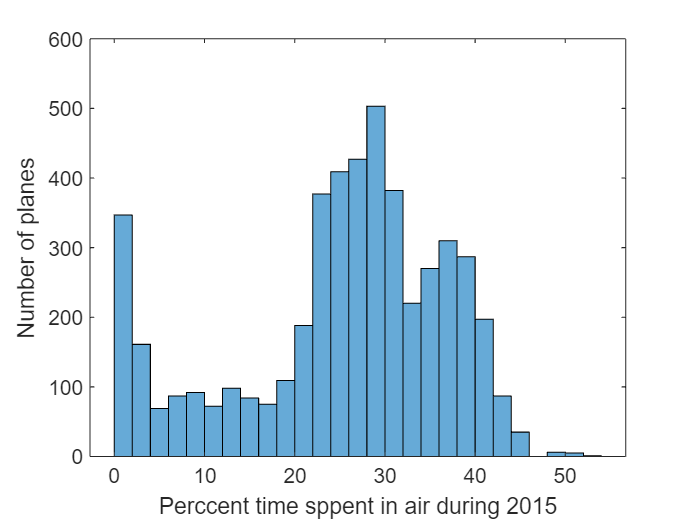

histogram(planeAirSummary.PercentTimeInAir)
xlabel("Percent time spent in air during 2015")
ylabel("Number of planes")